
==================== Dataset: FD002 ====================



--- Alpha = 95.0% ---


Alpha = 95.0% | TPR = 19.7% | FAR = 80.3% | Mean Lead Time  = 115.69 cycles



--- Alpha = 99.0% ---


Alpha = 99.0% | TPR = 21.6% | FAR = 62.2% | Mean Lead Time  = 101.32 cycles



--- Alpha = 99.5% ---


Alpha = 99.5% | TPR = 25.5% | FAR = 47.1% | Mean Lead Time  = 86.81 cycles


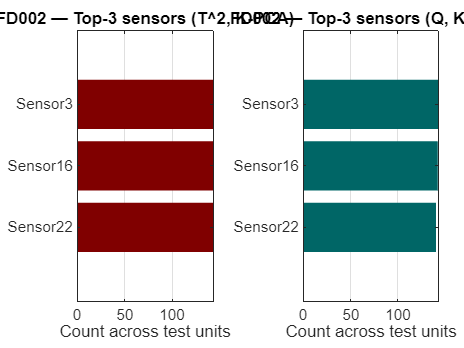


==================== Dataset: FD004 ====================



--- Alpha = 95.0% ---


Alpha = 95.0% | TPR = 13.7% | FAR = 84.7% | Mean Lead Time  = 151.09 cycles



--- Alpha = 99.0% ---


Alpha = 99.0% | TPR = 20.2% | FAR = 52.0% | Mean Lead Time  = 113.85 cycles



--- Alpha = 99.5% ---


Alpha = 99.5% | TPR = 21.4% | FAR = 36.7% | Mean Lead Time  = 98.57 cycles


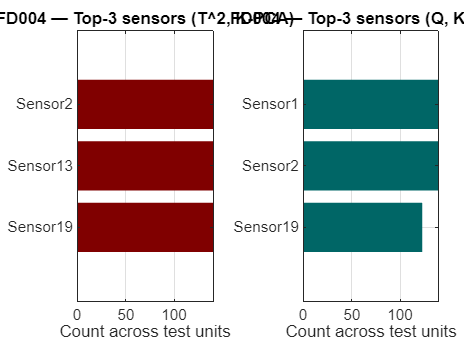

clear; close all; clc

% Training set
trainFD002 = readmatrix('train_FD002.txt');
trainFD004 = readmatrix('train_FD004.txt');

% Test set
testFD002 = readmatrix('test_FD002.txt');
testFD004 = readmatrix('test_FD004.txt');

% Dataset 
trainSets = {trainFD002, trainFD004};
testSets  = {testFD002,  testFD004};
dataset_names = {'FD002','FD004'};

function T2 = t2comp(data, loadings, latent)
    k = size(loadings,2);
    scores = data*loadings;
    latent_rep = repmat(sqrt(latent(1:k))', size(scores,1),1);
    standscores = scores ./ latent_rep;
    T2 = sum(standscores.^2,2);
end
function Q = qcomp(data, loadings)
    k = size(loadings,2);
    scores = data*loadings;
    reconstructed = scores*loadings';
    residuals = data - reconstructed;
    Q = sum(residuals.^2,2);
end

lead_window   = 50;  
alpha_levels  = [0.95, 0.99, 0.995];

for f = 1:numel(trainSets)
    fprintf('\n==================== Dataset: %s ====================\n', dataset_names{f});
    trainData = trainSets{f};
    testData  = testSets{f};

    unit_train  = trainData(:,1);
    cycle_train = trainData(:,2);
    X_train     = trainData(:,3:end);
    X_test_all  = testData(:,3:end);
    test_units  = unique(testData(:,1));
    total_engines = numel(test_units);

    % Remove constant variables
    constVars = find(var(X_train)==0);
    if ~isempty(constVars)
        X_train(:,constVars) = [];
        X_test_all(:,constVars) = [];
    end
    nVar = size(X_train,2);
    varNames = arrayfun(@(x) sprintf('Sensor%d',x), 1:nVar, 'UniformOutput', false);

    % Healthy Data: first 30% cycles per unit
    uniqueUnits = unique(unit_train);
    healthy_data_indices = [];
    for i = 1:numel(uniqueUnits)
        unit_id = uniqueUnits(i);
        idx = find(unit_train==unit_id);
        max_cycle = max(cycle_train(idx));
        healthy_data_indices = [healthy_data_indices; idx(cycle_train(idx) <= floor(0.3*max_cycle))];
    end
    X_healthy = X_train(healthy_data_indices,:);

    %  K-PCA
    % scaling
    mu = mean(X_healthy);
    sig = std(X_healthy);
    Xh_scaled = (X_healthy - mu)./sig;

    % Fit K-PCA with RBF (gamma via median trick) and centering in feature space
    maxCompCap = min(30, size(Xh_scaled,1)-1);
    KPCA = kpca_fit_local(Xh_scaled, maxCompCap);

    % Choose components for 90% variance in feature space
    k = find(KPCA.cumexp>=90,1); if isempty(k), k = numel(KPCA.lambda); end
    KPCA.V       = KPCA.V(:,1:k);
    KPCA.lambda  = KPCA.lambda(1:k);
    KPCA.T_train = KPCA.T_train(:,1:k);
    KPCA.explained = KPCA.explained(1:k);
    KPCA.cumexp    = KPCA.cumexp(1:k);

    % T^2 and Q on healthy
    Kc_row_norm = sum(KPCA.Kc_train.^2,2);
    T2_h = sum((KPCA.T_train.^2) .* (1./KPCA.lambda'), 2);
    Q_h  = max(Kc_row_norm - sum(KPCA.T_train.^2,2), 0);

    for a = 1:numel(alpha_levels)
        alpha = alpha_levels(a);
        alarm_T2 = prctile(T2_h, alpha*100);
        alarm_Q  = prctile(Q_h,  alpha*100);

        TP = 0; FP = 0; leadtimes = [];

        fprintf('\n--- Alpha = %.1f%% ---\n', alpha*100);

        for u = 1:total_engines
            idx_test = find(testData(:,1) == test_units(u));
            X_test = X_test_all(idx_test,:);
            N_test = size(X_test,1);

            X_scaled = (X_test - mu) ./ sig;

            
            [T2_test, Q_test] = kpca_project_stats_local(X_scaled, Xh_scaled, KPCA);

            % First alarm (T^2 OR Q)
            alarm_idx_T2 = find(T2_test > alarm_T2,1);
            alarm_idx_Q  = find(Q_test > alarm_Q,1);
            if ~isempty(alarm_idx_T2)
                first_alarm = alarm_idx_T2;
            elseif ~isempty(alarm_idx_Q)
                first_alarm = alarm_idx_Q;
            else
                first_alarm = NaN;
            end

            % Lead time and classification
            if ~isnan(first_alarm)
                leadtime = N_test - first_alarm;
                leadtimes(end+1) = leadtime;
                if leadtime <= lead_window
                    TP = TP + 1;
                else
                    FP = FP + 1;
                end
            end
        end

        % Metriche globali
        TPR = 100*TP/total_engines;
        FAR = 100*FP/total_engines;
        mean_LT = mean(leadtimes,'omitnan');

        fprintf('Alpha = %.1f%% | TPR = %.1f%% | FAR = %.1f%% | Mean Lead Time  = %.2f cycles\n', ...
            alpha*100, TPR, FAR, mean_LT);
    end

    alpha = alpha_levels(1);
    alarm_T2 = prctile(T2_h, alpha*100);
    alarm_Q  = prctile(Q_h,  alpha*100);

    freq_T2 = zeros(1,nVar);
    freq_Q  = zeros(1,nVar);

    eps_pert = 0.25; 

    for u = 1:total_engines
        idx_test = find(testData(:,1) == test_units(u));
        X_test   = X_test_all(idx_test,:);
        N_test   = size(X_test,1);

        X_scaled = (X_test - mu) ./ sig;

        [T2_test, Q_test] = kpca_project_stats_local(X_scaled, Xh_scaled, KPCA);

        % First alarm (T^2 OR Q)
        viol = (T2_test > alarm_T2) | (Q_test > alarm_Q);
        first_alarm = find(viol, 1, 'first');
        if isempty(first_alarm), continue; end

        x0 = X_scaled(first_alarm,:);  
        [dT2_abs, dQ_abs] = kpca_point_sensitivity(x0, Xh_scaled, KPCA, eps_pert);

        % Rank for T²
        [~, idxT2] = sort(dT2_abs, 'descend');
        topN = min(3, nVar);
        freq_T2(idxT2(1:topN)) = freq_T2(idxT2(1:topN)) + 1;

        % Rank for Q
        [~, idxQ]  = sort(dQ_abs,  'descend');
        freq_Q(idxQ(1:topN))     = freq_Q(idxQ(1:topN)) + 1;
    end

    % Plot Top-3 
    topN = min(3, nVar);
    [valsT2, indsT2] = maxk(freq_T2, topN);
    [valsQ,  indsQ ] = maxk(freq_Q,  topN);

    namesT2 = varNames(indsT2);
    namesQ  = varNames(indsQ);

    figure('Color','w','Name',sprintf('%s — Top-3 sensors (K-PCA sensitivity)', dataset_names{f}));
    tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

    % Subplot T^2
    nexttile; 
    barh(flip(valsT2),'FaceColor',[0.50 0.00 0.00],'EdgeColor','none'); grid on; box on;
    yticks(1:topN);
    yticklabels(flip(namesT2));
    xlabel('Count across test units');
    title(sprintf('%s — Top-3 sensors (T^2, K-PCA)', dataset_names{f}), 'Interpreter','none');

    % Subplot Q
    nexttile; 
    barh(flip(valsQ),'FaceColor',[0.00 0.40 0.40],'EdgeColor','none'); grid on; box on;
    yticks(1:topN); 
    yticklabels(flip(namesQ));
    xlabel('Count across test units');
    title(sprintf('%s — Top-3 sensors (Q, K-PCA)', dataset_names{f}), 'Interpreter','none');
end



% ===================== Fuctions K-PCA =====================
function KPCA = kpca_fit_local(X, maxCompCap)
    % Kernel RBF with gamma via median trick; centering in feature space
    D2 = pdist2(X,X,'euclidean').^2;
    m = median(D2(D2>0),'all');
    if isempty(m) || ~isfinite(m) || m<=0, m = 1; end
    gamma = 1/(2*m);

    K = exp(-gamma * D2);          
    N = size(K,1);
    H = eye(N) - (1/N)*ones(N);
    Kc = H*K*H;

    % Eigendecomposition
    maxcomp = min([maxCompCap, N-1]);
    opts.isreal = true; opts.issym = true;
    try
        [V,L] = eigs((Kc+Kc')/2, maxcomp, 'largestreal', opts);
        lambda = diag(L);
    catch
        [V,L] = eig((Kc+Kc')/2);
        [lambda, idx] = sort(real(diag(L)), 'descend');
        V = real(V(:,idx));
        V = V(:, 1:maxcomp);
        lambda = lambda(1:maxcomp);
    end
    pos = lambda > max(1e-9, 1e-12*max(lambda));
    V = V(:,pos); lambda = lambda(pos);

    % Scores in feature space
    T = Kc * (V ./ sqrt(lambda'));

    explained = 100*lambda/sum(lambda);
    cumexp = cumsum(explained);

    KPCA.gamma    = gamma;
    KPCA.V        = V;
    KPCA.lambda   = lambda;
    KPCA.T_train  = T;
    KPCA.K_train  = K;
    KPCA.Kc_train = Kc;
    KPCA.meanKrow = mean(K,2);
    KPCA.meanK    = mean(K,'all');
    KPCA.explained = explained;
    KPCA.cumexp    = cumexp;
end

function [T2, Q] = kpca_project_stats_local(X_new, X_train, KPCA)
    M = size(X_new,1);
    N = size(X_train,1);
    Kxt = exp(-KPCA.gamma * pdist2(X_new, X_train,'euclidean').^2); % M x N

    oneN = (1/N)*ones(N,1);
    Kc_new = Kxt ...
           - Kxt*oneN*ones(1,N) ...
           - ones(M,1)*KPCA.meanKrow' ...
           + KPCA.meanK;

    T = Kc_new * (KPCA.V ./ sqrt(KPCA.lambda'));
    T2 = sum((T.^2) .* (1./KPCA.lambda'), 2);

    Kc_row_norm = sum(Kc_new.^2,2);
    Q = max(Kc_row_norm - sum(T.^2,2), 0);
end

function [dT2_abs, dQ_abs] = kpca_point_sensitivity(x0, Xh_scaled, KPCA, eps_pert)
    P = size(x0,2);
    dT2_abs = zeros(1,P);
    dQ_abs  = zeros(1,P);

    % baseline
    [T2_base, Q_base] = kpca_project_stats_local(x0, Xh_scaled, KPCA);

    for j = 1:P
        x_eps = x0;
        x_eps(j) = x_eps(j) + eps_pert;
        [T2_eps, Q_eps] = kpca_project_stats_local(x_eps, Xh_scaled, KPCA);
        dT2_abs(j) = abs(T2_eps - T2_base);
        dQ_abs(j)  = abs(Q_eps  - Q_base);
    end
end
